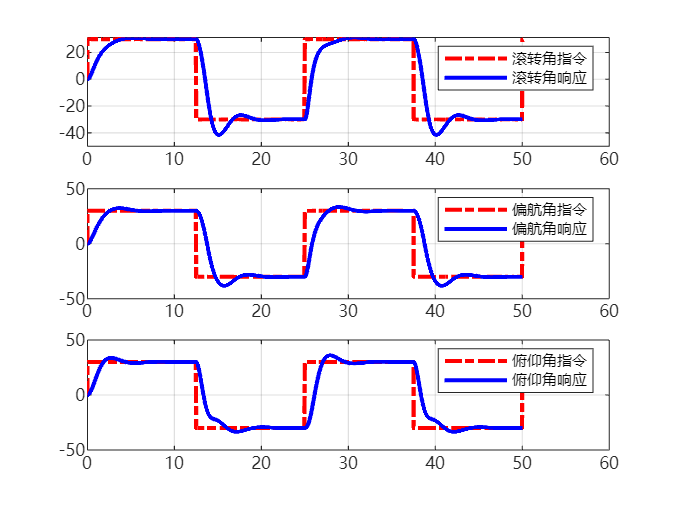

%% 参数设置
close all,clear,clc,
tic,
global J1 J2 J3;
J1 = 1000;  J2 = 1500;  J3 = 1800;

% 初始化参数
t0 = 0.0;
dt = 0.01;
tf = 50.0;
tout = t0:dt:tf;

theta1 = deg2rad(0);
theta2 = deg2rad(0);
theta3 = deg2rad(0);
omega1 = deg2rad(0);
omega2 = deg2rad(0);
omega3 = deg2rad(0);
state = [theta1;theta2;theta3;omega1;omega2;omega3];
stateout = state;
uout = []; % 控制方程u

% PD参数设置
kp1 = -2000;    kd1 = -2000;
kp2 = -3000;    kd2 = -3000;
kp3 = -3600;    kd3 = -3600;

%三轴方波周期
T1 = 25;    T2 = 25;    T3 = 25;

theta1cout = [];
theta2cout = [];
theta3cout = [];

%% 仿真
% 迭代
for t=t0:dt:tf
    theta1c = 30*pi/180*sign(sin(2*pi/T1*t));
    theta2c = 30*pi/180*sign(sin(2*pi/T2*t));
    theta3c = 30*pi/180*sign(sin(2*pi/T3*t));
    theta1cout = [theta1cout, theta1c];
    theta2cout = [theta2cout, theta2c];
    theta3cout = [theta3cout, theta3c];

    error1 = theta1 - theta1c;
    error2 = theta2 - theta2c;
    error3 = theta3 - theta3c;

    M1 = kp1*error1 + kd1*omega1;  %跟随方波，所以改为误差值，其他控制不变
    M2 = kp2*error2 + kd2*omega2;
    M3 = kp3*error3 + kd3*omega3;
    u = [M1;M2;M3];
    uout = [uout, u];

    % 迭代方程组
    ke1 = statequation06(t, state, u);
    ke2 = statequation06(t+0.5*dt, state+0.5*ke1*dt, u);
    ke3 = statequation06(t+0.5*dt, state+0.5*ke2*dt, u);
    ke4 = statequation06(t+dt, state+ke3*dt, u);
    state = state + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    stateout = [stateout, state];

    % 状态变量更新
    theta1 = state(1);
    theta2 = state(2);
    theta3 = state(3);
    omega1 = state(4);
    omega2 = state(5);
    omega3 = state(6);
end

theta1out = stateout(1, :);
theta2out = stateout(2, :);
theta3out = stateout(3, :);
omega1out = stateout(4, :);
omega2out = stateout(5, :);
omega3out  = stateout(6, :);
% 循环最后一次更新
tout = [tout, tout(end)+dt];

M1out = uout(1, :);
M2out = uout(2, :);
M3out = uout(3, :);
M1out = [M1out, M1out(end)];
M2out = [M2out, M2out(end)];
M3out = [M3out, M3out(end)];

theta1cout = [theta1cout, theta1cout(end)];
theta2cout = [theta2cout, theta2cout(end)];
theta3cout = [theta3cout, theta3cout(end)];
%% 绘图
% 画图
figure;
subplot(3, 1, 1),
plot(tout, theta1cout*180/pi, 'r-.', tout, rad2deg(theta1out), 'b', 'LineWidth', 2);
set(gca, 'fontname', 'microsoft yahei');
legend('滚转角指令', '滚转角响应');
grid on;

subplot(3, 1, 2),
plot(tout, theta2cout*180/pi, 'r-.', tout, rad2deg(theta2out), 'b', 'LineWidth', 2);
set(gca, 'fontname', 'microsoft yahei');
legend('偏航角指令', '偏航角响应');
grid on;

subplot(3, 1, 3),
plot(tout, theta3cout*180/pi, 'r-.', tout, rad2deg(theta3out), 'b', 'LineWidth', 2);
set(gca, 'fontname', 'microsoft yahei');
legend('俯仰角指令', '俯仰角响应');
grid on;


toc,

历时 0.226639 秒。



%% 函数

function output=statequation06(t, state, u)
global J1 J2 J3;  % 转动惯量
% state = [theta1;theta2;theta3;omega1;omega2;omega3];
% 获取此刻状态
theta1 = state(1);
theta2 = state(2);
theta3 = state(3);
omega1 = state(4);
omega2 = state(5);
omega3 = state(6);
M1 = u(1);
M2 = u(2);
M3 = u(3);

% 计算导数。作为状态输出
theta1dot = omega1 - omega2*cos(theta1)*tan(theta3) + omega3*sin(theta1)*tan(theta3);
theta2dot = omega2*cos(theta1)/cos(theta3) - omega3*sin(theta1)/cos(theta3);
theta3dot = omega2*sin(theta1) + omega3*cos(theta1);
omega1dot = (J2-J3)/J1*omega2*omega3 + M1/J1;
omega2dot = (J3-J1)/J2*omega1*omega3 + M2/J2;
omega3dot = (J1-J2)/J3*omega1*omega2 + M3/J3;

output = [theta1dot;theta2dot;theta3dot;omega1dot;omega2dot;omega3dot];
end